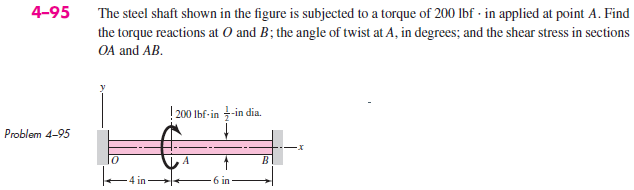

# given

u = symunit; % problem is done completely wrong!!!!!!!!!!!!!
D = 0.5*u.in;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ro', 0);
b = b.add('reaction', 'moment', 'Mo', 0);
b = b.add('applied', 'moment', -200*u.lbf*u.in, 4*u.in);
b = b.add('reaction', 'force', 'Rb', 10*u.in);
b = b.add('reaction', 'moment', 'Mb', 10*u.in);
b.L = 10*u.in;

# section properties

b.E = 30e6*u.lbf/u.in^2;
b.I = sympi*(D/2)^4/4;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y

$$y(x) = \left\{ \begin{array}{cl} -\frac{32\,x^{2}\,\left(2\,x-5\,\mathrm{in}\right)}{390625\,\pi }\,\frac{1}{{\mathrm{in}}^{2}} & \text{ if }x\leq 4\,\mathrm{in}\\ -\frac{64\,{\left(x-10\,\mathrm{in}\right)}^{2}\,\left(3\,x-10\,\mathrm{in}\right)}{1171875\,\pi }\,\frac{1}{{\mathrm{in}}^{2}} & \text{ if }4\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{64\,x\,\left(3\,x-5\,\mathrm{in}\right)}{390625\,\pi }\,\frac{1}{{\mathrm{in}}^{2}} & \text{ if }x\leq 4\,\mathrm{in}\\ -\frac{64\,\left(x-10\,\mathrm{in}\right)\,\left(9\,x-50\,\mathrm{in}\right)}{1171875\,\pi }\,\frac{1}{{\mathrm{in}}^{2}} & \text{ if }4\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{24\,\left(6\,x-5\,\mathrm{in}\right)}{5}\,\mathrm{lbf} & \text{ if }x\leq 4\,\mathrm{in}\\ -\frac{16\,\left(9\,x-70\,\mathrm{in}\right)}{5}\,\mathrm{lbf} & \text{ if }4\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = -\frac{144}{5}\,\mathrm{lbf}$$

w

$$w(x) = 0$$

addvar(y);
b.E = rewrite(b.E, u.psi);

# reactions

Ro = vpa(r.Ro) %#ok

$$Ro = -28.8\,\mathrm{lbf}$$

Mo = r.Mo %#ok

$$Mo = -24\,\mathrm{in}\,\mathrm{lbf}$$

Rb = vpa(r.Rb) %#ok

$$Rb = 28.8\,\mathrm{lbf}$$

Mb = r.Mb %#ok

$$Mb = -64\,\mathrm{in}\,\mathrm{lbf}$$

clear Ro Mo Rb Mb;

# shear and moment diagram

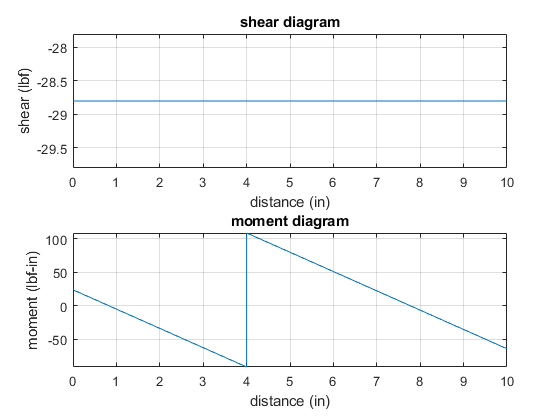

beam.shear_moment(m, v, [0 b.L], {'lbf' 'in'});

# shear in the beam

V_OA_and_AB_vpa = formula(vpa(v)) %#ok

$$V\_OA\_and\_AB\_vpa = -28.8\,\mathrm{lbf}$$

clear V_OA_and_AB_vpa;

# angle of twist at A

thetaA = rewrite(dy(4*u.in)*u.rad, u.deg);
thetaA_vpa = vpa(thetaA) %#ok

$$thetaA\_vpa = -0.0836663321489215271857606647115\,\deg$$

clear thetaA_vpa;